# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
setpref('ISET', 'fast_num2string', true); % use faster piWrite
sceneLuminance = 200;
numRays = 64;
filmResolution = 512;

sceneChoice = "Chess Set";
apertureDiameter = 6;% in mm

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','wide.40deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter); % realistic camera needs .dat

Read 8 materials.
Read 3 textures.
***Scene parsed.



pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, ...
    'sceneLuminance', sceneLuminance);

Read 8 materials.
Read 3 textures.
***Scene parsed.


%pinholeCPScene.thisR.set('focaldistance', '.005');

if strcmp(sceneChoice, "CornellBoxReference")
    bunny = load('bunny.mat');
    [~, bunny_id] = pbrtCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    [~, bunny_id] = pinholeCPScene.thisR.set('asset',1, 'add', bunny.assetTree.Node{1});
    pinholeCPScene.thisR.set('material', 'add', bunny.matList{1});
    
    % in case bunny is out of our frame
    pinholeCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    pbrtCPScene.thisR.set('asset', bunny_id, 'translate', [0 .1 0]);
    %if you want object motion
    %pbrtCPScene.objectMotion = {{bunny_id, [0 .1 0], [0 0 0]}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', bunny_id, 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;
    
    mcc = load('mccCB.mat');
    [~, mcc_id] = pbrtCPScene.thisR.set('asset',1, 'add', mcc.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', mcc.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    [~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR.set('asset',1, 'add', coord.assetTree.Node{1});
    pbrtCPScene.thisR.set('material', 'add', coord.matList{1});
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorCreate('imx363'); 

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% try to make the pinhole a pinhole:)
% if it works, should integrate into cpCamera
pinholeCamera = cpBurstCamera();
pinholeCamera.cmodules(1) = cpCModule('sensor', sensor);
pinholeCamera.cmodules(1).oi.optics = opticsSet(pinholeCamera.cmodules(1).oi.optics,'fnumber',64);

% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

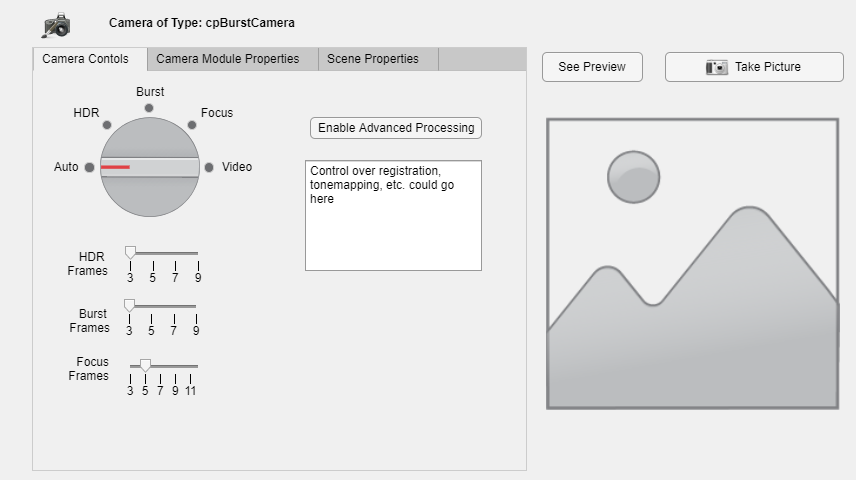

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 1.296674 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.51
Render: docker --context render-vista exec -i  pbrt-gpu-Windows19289 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.16
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.40
Complete render took: 1.05e+01 seconds.*** Rendering time for ChessSet:  10.5 sec ***

exr2bin done.exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/ise

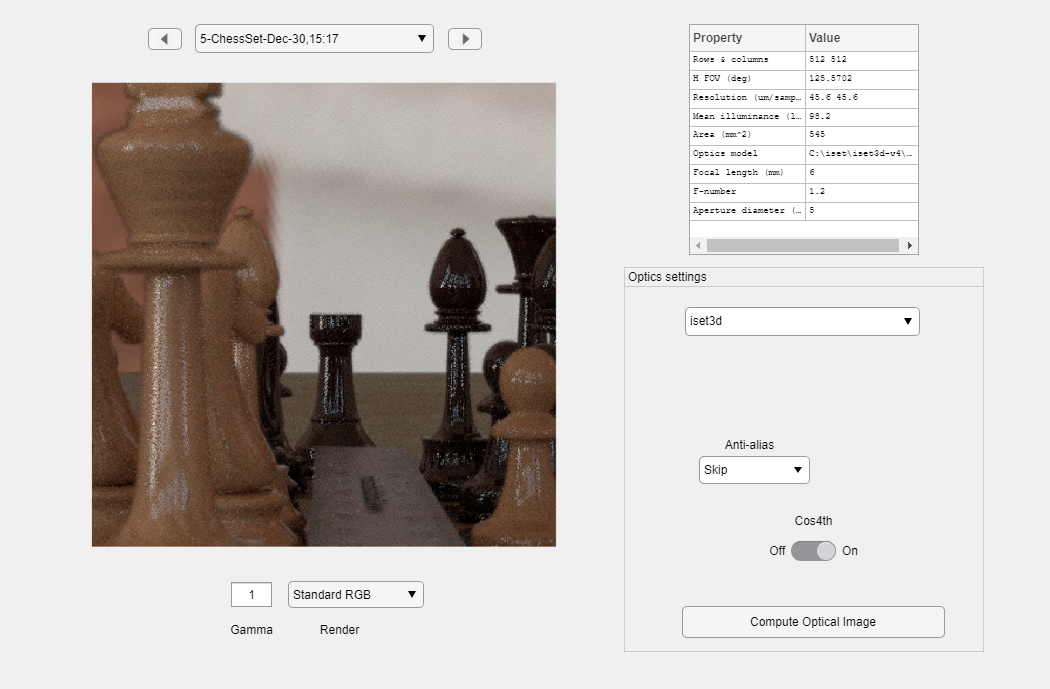

Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 1.426915 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.30
Render: docker --context render-vista exec -i  pbrt-gpu-Windows19289 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.02
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.29
Complete render took: 9.80e+00 seconds.*** Rendering time for ChessSet:  9.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.18
Render: docker --context render-vista exec -i  pbrt-gpu-Windows19289 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   6.01
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   0.97
Complete render took: 9.23e+00 seconds.*** Rendering time for ChessSet:  9.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 2.011578 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford

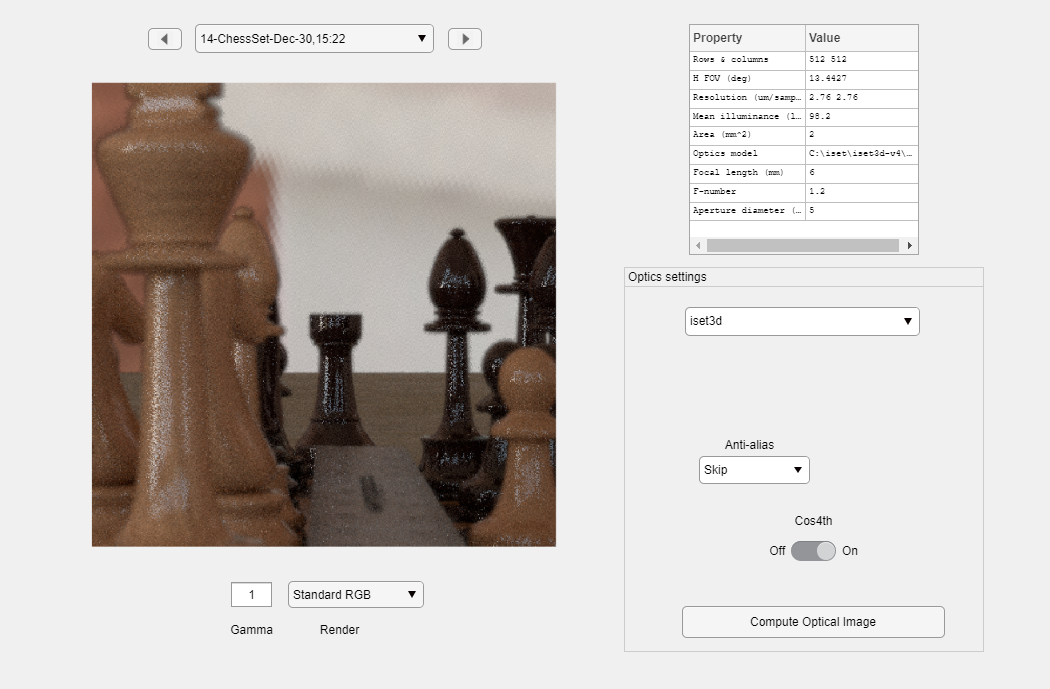

Fmeasure     
SMeasure[100%]
Weights [100%]
Fusion [100%]

Elapsed time: 0.62 s:
Reading  (47.6%).
Fmeasure (34.2%).
SMeasure (11.1%).
Fusion   (7.1%).



stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 9, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Overwriting PBRT file C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt
Elapsed time is 1.239315 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.15
Render: docker --context render-vista exec -i  pbrt-gpu-Windows19289 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in:   5.89
Success!
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.71
Complete render took: 9.72e+00 seconds.*** Rendering time for ChessSet:  9.7 sec ***

exr2bin done.exr2bin done. Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset

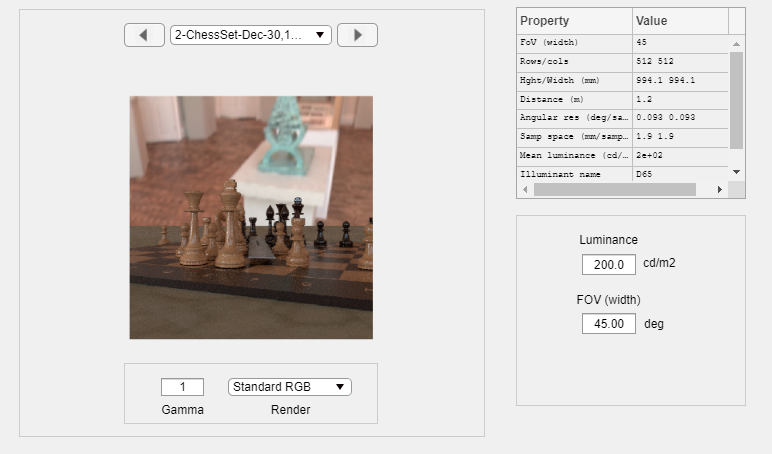


pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

Burst vs. Stacked with no motion

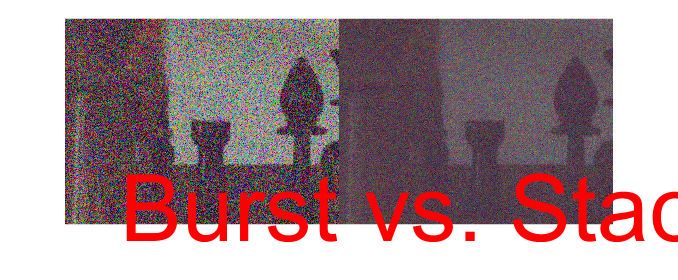


cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');

Pinhole vs. Stacked with no motion

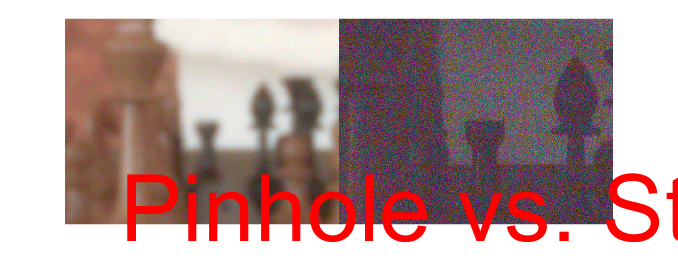

cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');

Pinhole vs. Burst with no motion

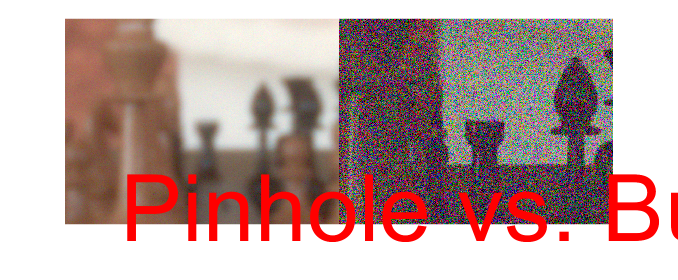

cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 

cpCompare ran  on: NVIDIA Corporation Quadro T2000/PCIe/SSE2with driver version: 4.6.0 NVIDIA 472.39


disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));

cpCompare ran  in: 294.875 seconds of CPU time.


disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));

cpCompare ran  in: 552.0711 total seconds.
